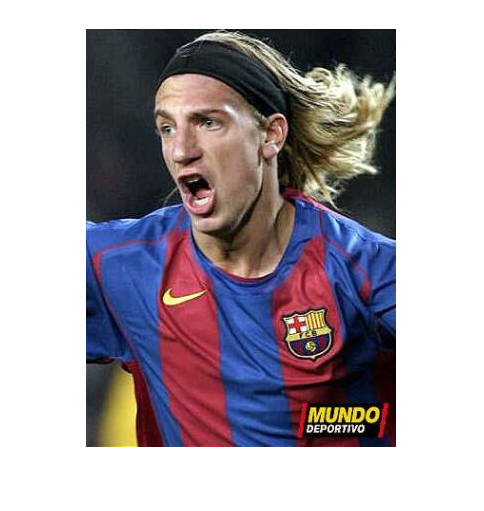

clear all
image=imread('05.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocks = 4 

numBlocks = 4

rowSize = uint32(row/numBlocks)

RowSize = uint32
105

colSize = uint32(col/numBlocks)

ColSize = uint32
78


endrow = uint32(row*8)

endrow = uint32
3344

endcol = uint32(col*5)

endcol = uint32
1550

startrow = uint32
0

for i = 1:numBlocks
    for j= 1:numBlocks
        startrow = j*rowSize - rowSize + 1;
        startcol = i*colSize - colSize + 1;
        
    end
end
for y = startrow:endrow 
    for x = startcol:endcol 
      Red = Image_red(y,x);
      Green = Image_green(y,x);
      Blue = Image_blue(y,x);
    
      NormalizedRed = Red/(Red + Green + Blue);
      NormalizedGreen = Green/(Red + Green + Blue);
      NormalizedBlue = Blue/(Red + Green + Blue);
    
      Image_red(y,x) = NormalizedRed;
      Image_green(y,x) = NormalizedGreen;
      Image_blue(y,x) = NormalizedBlue;
    end
end

Undefined function or variable 'startcol'.

image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

figure; imshow(uint8(255*image));

% histogram(image, nBins)
histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')
histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')
histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')